## **Linear Algebra Group Project - Bethany Wu & Alex Stapley**

### **Problem 2: Implement the GMRES Algorithm**

**Test**

A= [1 4 7; 2 9 7; 5 8 3];
b = [1; 8; 2];
M = diag(ones(3,1)); % M is an identity matrix which shouldn't affect the output

% Same output means our GMRES algorithm works!
gmres_test(3,A,b);

   13.0580    5.4098   -1.5669
    7.4335    3.9987    1.0668
         0    2.6318   -4.0567
         0         0    0.0000

    0.1204    0.5497    0.8266         0
    0.9631   -0.2666    0.0370    0.5487
    0.2408    0.7917   -0.5615    0.8360



gmres_BA(3,b,zeros(3,1),3,M,A);

### Problem 3: Solve the FEM Problem

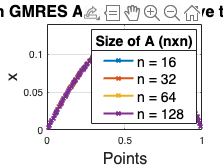

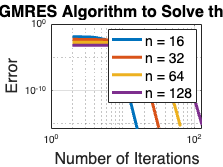

% For V(x) = 1
FEM(0);

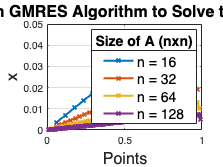

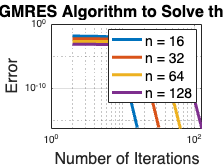

% For V(x) = n + 1
FEM(1)

# Functions

#### 'FEM' function for solving the finite-element formulation of the variational problem for different V(x) = gamma

function FEM(m)
    ns = [16 32 64 128];
    Is = [2 4 8 16 32 64 128];
    error_thresh = 10e-6;
    figure(1);
    figure(2);
    for n = ns
        gamma = n*m+1;
        errors = []; iters = [];
        [A,b] = BVPtoVar(n,gamma);
        M = diag(ones(n,1));
        x0 = zeros(n,1);
        for I = Is
            if I > n
                break;
            end
            x = gmres_BA(I,b,x0,n,M,A);
            e = norm(b-A*x')/n;
            errors = [errors e];
            iters = [iters I];
            if e < error_thresh
                points = linspace(0,1,n+2);
                figure(2); plot(points(2:end-1),x,'LineWidth',2); hold on;
                break;
            end
        end
        figure(1); loglog(iters,errors,'LineWidth',3); hold on;
    end

    figure(1); title('Error from GMRES Algorithm to Solve the FEM Problem','FontSize',16);
    xlabel('Number of Iterations','FontSize',16); ylabel('Error','FontSize',16);
    legend('n = 16','n = 32','n = 64','n = 128','FontSize',14); grid on; hold off;

    figure(2); title('Solution from GMRES Algorithm to Solve the FEM Problem','FontSize',16);
    xlabel('Points','FontSize',16); ylabel('x','FontSize',16);
    leg = legend('n = 16','n = 32','n = 64','n = 128','FontSize',14); title(leg,'Size of A (nxn)','FontSize',14);
    grid on; hold off;
end

#### 'BVPtoVar' (boundary value problem to variational problem) function from Problem 1 (P1.mlx)

function [A,b] = BVPtoVar(n,gamma)
    dx = 1/(n+1);
    % Forming A1
    side_A1 = ones(n-1,1)*(-1/(dx));
    diag_A1 = ones(n,1)*(2/dx); 
    A1 = diag(side_A1,-1)+diag(diag_A1)+diag(side_A1,1);
    % Forming A2
    side_A2 = ones(n-1,1)*(gamma/2);
    A2 = diag(-side_A2,-1)+diag(side_A2,1);

    A = A1+A2;
    b = ones(n,1)*dx;
end

#### The GMRES algorithm with a preconditioner matrix, M

function x = gmres_BA(I,b,x0,n,M,A)
    r0 = b-A*x0;
    beta = norm(r0);
    V = zeros(n,n+1); W = zeros(n);
    V(:,1) = r0/beta;
    H = zeros(n+1,n); 
    for j = 1:I
        W(:,j) = A*V(:,j);
        for i = 1:j+1
            H(i,j) = dot(W(:,j),M*V(:,i));
            W(:,j) = W(:,j)-H(i,j)*V(:,i);
        end
        H(j+1,j) = norm(W(:,j));
        if H(j+1,j) == 0
            break;
        end
        V(:,j+1) = W(:,j)./H(j+1,j);
    end
    [n,m] = size(H);
    a = zeros(n,1); a(1) = beta;
    ys = lsqlin(H,a);
    for i = 1:length(ys)
        x(i) = V(i,1:length(ys))*ys;
    end
end

#### GMRES algorithm from Shitao Fan paper

function [x,y,V,H] = gmres_test(I,A,b)
    r0 = b;
    beta = norm(r0);
    V(:,1) = r0/beta;
    H = [];
    for j = 1:I
        W(:,j) = A*V(:,j);
        for i = 1:j
            H(i,j) = dot(W(:,j),V(:,i));
            W(:,j) = W(:,j)-H(i,j)*V(:,i);
        end
        H(j+1,j) = norm(W(:,j));
        if H(j+1,j) == 0
            break;
        end
        V(:,j+1) = W(:,j)./H(j+1,j);
    end
    [n,m] = size(H);
    a = zeros(n,1); a(1) = beta;
    y = lsqlin(H,a);
    for i = 1:length(y)
        x(i) = V(i,1:length(y))*y;
    end
    disp(H);
    disp(V);
end